Laborator 9 - Aproximare prin metoda celor mai mici pătrate

P1. Să se găsească aproximanta discretă prin metoda celor mai mici pătrate pentru ponderea w(x) = 1 și baza 1, x, x^2, ..., x^n.

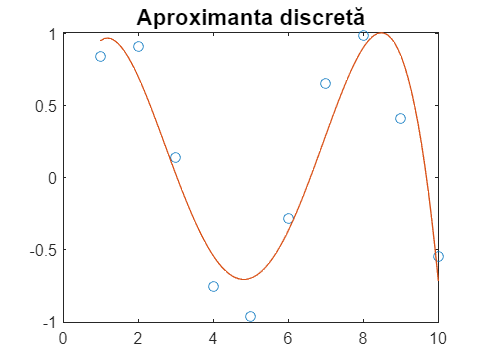

% n = 4
x = 1 : 10;
y = sin(1 : 10);

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4];

x_approx = x(1) : (x(length(x)) - x(1)) / 100 : x(length(x));
y_approx = least_squares_approx(x, y, phi, x_approx);

plot(x, y, 'o', x_approx, y_approx, '-');
title("Aproximanta discretă", "FontSize", 14);

P2. Un asteroid ce orbitează în jurul Soarelui a putut fi observat timp de câteva zile înainte să dispară. Se dorește calcularea traiectoriei pe baza celor 10 observații, pentru a putea prevedea situația când orbita va fi din nou vizibilă.

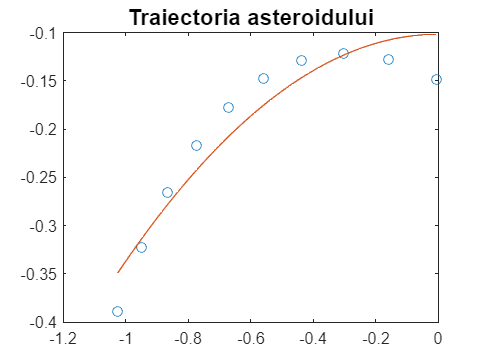

x = [-1.024940 -0.949898 -0.866114 -0.773392 -0.671372 -0.559524 -0.437067 -0.302909 -0.159493 -0.007464];
y = [-0.389269 -0.322894 -0.265256 -0.216557 -0.177152 -0.147582 -0.128618 -0.121353 -0.127348 -0.148895];

% Model parabolic
phi = @(x)[ones(1, length(x)); x.^2];

x_approx = x(1):(x(length(x)) - x(1)) / 100 : x(length(x));
y_approx = least_squares_approx(x, y, phi, x_approx);

plot(x, y, 'o', x_approx, y_approx, '-');
title("Traiectoria asteroidului", "FontSize", 14);

P3. La măsurarea unui segment de drum, presupunem că am efectuat 5 măsurători:

*AD = 89m, AC = 67m, BD = 53m, AB = 35m, CD = 20m.*

Să se determine lungimile segmentelor x1 = AB, x2 = BC și x3 = CD.

% A - B - C - D
% AB = x1; BC = x2; CD = x3;
% X = [ AD; AC; BD; AB; CD] 
X = [1 1 1; 1 1 0; 0 1 1; 1 0 0; 0 0 1];
Y = [89; 67; 53; 35; 20];

a = linsolve(X, Y);
AB = a(1,1);
BC = a(2,1);
CD = a(3, 1);
fprintf("AB = %7.2f, BC = %7.2f, CD = %7.2f", AB, BC, CD);

AB =   35.13, BC =   32.50, CD =   20.63

P4. Datele următoare dau populația SUA (în milioane) determinată de recensăminte de US Census, între anii 1900 și 2010. Dorim să modelăm populația și să o estimăm pentru anii 1975 și 2010.

Modelați populația printr-un model polinomial de gradul 3

și printr-un model exponențial

% Potrivire polinomială:
y = [75995 91972 105710 123200 131670 150700 179320 203210 226510 249630 281420 308790]';
t = (1900:10:2010)';
x = (1890:1:2019)';
w = 1975;

fprintf("Potrivire polinomială:");

Potrivire polinomială:

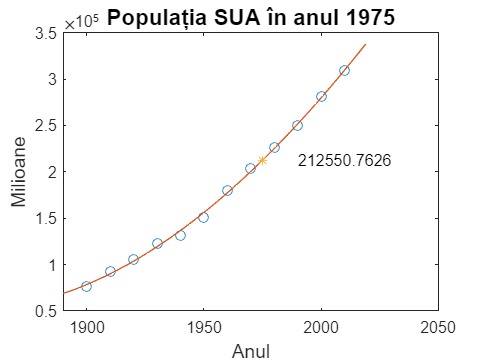


s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, (1975 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 1975", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);

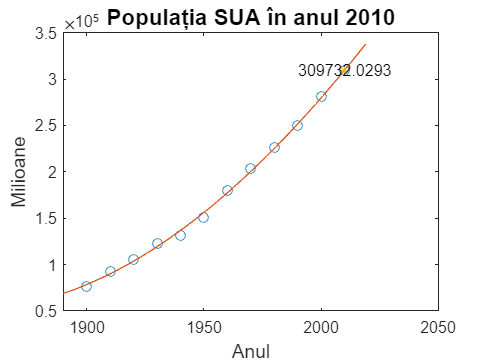


w = 2010;

s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, (2010 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 2010", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);